# Subspace Methods

**Signal length**

Try increasing the signal length to see what happens in each PSD plot.

This script compares the eigenvector method (subspace), Welch's method (nonparametric), and the periodogram (nonparametric). The dropdown at the top of the script sets the duration of the signal.

Subspace methods work particularly well when the signal contains a lot of white noise. When the duration is `0.1`, all 3 tones can be identified with the subspace method. Noisy signals generally work better with Welch's method, but the signal is too short for spectral averaging to be effective. In the periodogram, you can see the tones at 200 and 220 Hz, but the tone at 100 Hz is hidden in the noise.

fs = 1000;
t = (0:1/fs:0.5)';
disp(numel(t) + " samples")

501 samples


Generate a signal with 3 tones.

x = sin(2*pi*220*t) + sin(2*pi*200*t) + 0.1*sin(2*pi*100*t);
rng default
xn = x + 0.1*randn(size(x));

**Subspace dimension**

Choose the number of tones. The correct value is 6 because you should specify double the number of tones.

numtones = 6;

Try the eigenvector or MUSIC method.

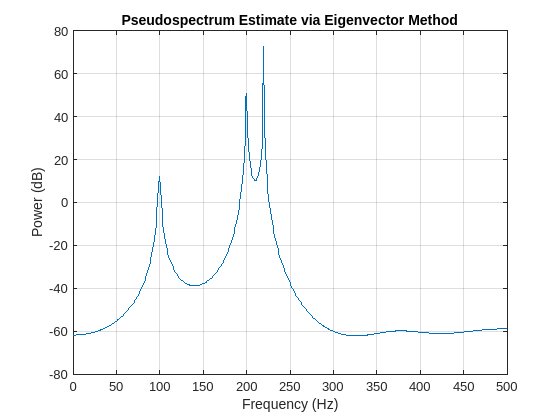

peig(xn,numtones,2^10,fs);

% pmusic(xn,numtones,2^10,fs);

For comparision, plot Welch method. 

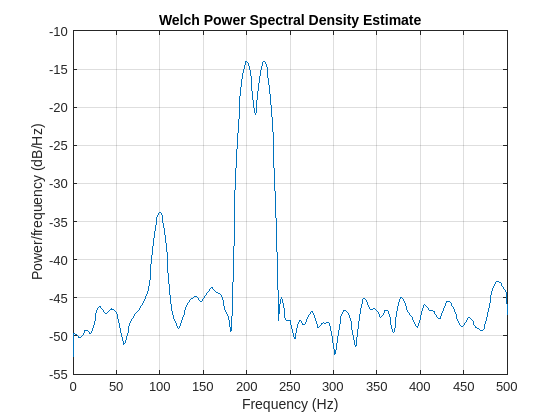

pwelch(xn,[],[],2^10,fs);

Periodogram is generally better for shorter signals because there's no spectral averaging, but it doesn't perform well here because the signal contains a lot of noise. If you'd like to see the periodogram, uncomment this line:

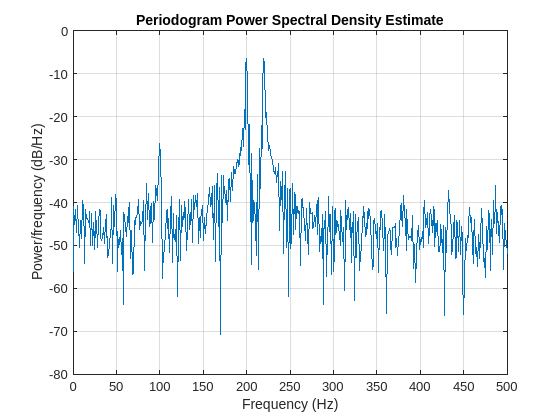

periodogram(xn,[],2^10,fs);